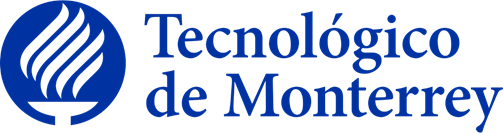

**Instituto Tecnológico y de Estudios Superiores de Monterrey**

TE3002B.502 

**Implementación de robótica Inteligente (Gpo 502)**

Semestre: febrero - junio 2023   

**Actividad:**

Actividad  8.1 - Modelado Cinematico de Piernas

**Alumno:**

		José Angel Ramírez Ramírez   	A01735529

**Profesor: Dr. Alfredo Garcia Suarez.**

Fecha de entrega: 26 de Mayo del 2023

## objetivos:

- **Crear** un nuevo repositorio con el nombre: **Actividad** **8.1 (Matriz de Transformación Homogénea T)**

- **Obtener** la matriz de  transformación **homogénea  T ** de los siguientes sistemas la cual relacione la posición y orientación del extremo del robot respecto a su sistema de referencia fijo (la base).

- **Implementar** el código requerido para generar el cálculo de las matrices **homogéneas (H1, H2, H3, etc.)** y la matriz de **transformación (T)** de cada sistema. Simulando cada una de las transformaciones desde la trama absoluta hasta la trama final.

## **Sistema 1**

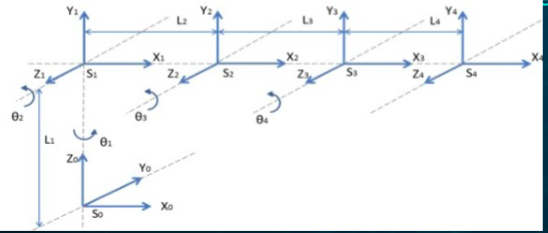

Como primer paso se  calculan las rotaciones y/0 trasformaciones que se necesarias para obtener las  matrices de transformacion homogeneas hasta llegar a la trama final, quedando de la siguiente manera:

H1 = rotx(90) Ty(l1)

H2 = Tx(l2)

H3 = Tx(l3)

H4 = Tx(l4)

Antes de iniciar limpiamos la pantalla, el workspace y cerramos cualquier ventana abierta. 

%Limpieza de pantalla
clear 
close all
clc

Luego declaramos las longitudes que hay entre las diferentes tramas. Estas longitudes son arbitrarias, pero tratan de hacemejar el resultado final con el de la imagen. 

%longitudes
l1 = 1;
l2 = 1;
l3 = 1; 
l4 = 1; 

Ahora calculamos las matrices de transformacion homogeneas con los resultados obtenido en el primer paso, considerando que partimos de las coordenadas (0,0,0)

%Calculamos las matrices de transformación homogénea
H0=SE3;

H1=SE3(rotx(deg2rad(90)), [0 0 l1]);
H2=SE3([l2 0 0]);
H3=SE3([l3 0 0]);
H4=SE3([l4 0 0]);

Una vez obtenidas las matrices anteriores, procedemos a calcular las Matriz de transformacion homogenea global a traves de la siguiente fomula:

aunque para este caso va de 4 a 0

H20= H1*H2;
H30= H20*H3; 
H40= H30*H4; %Matriz de transformación homogenea global de 4 a 0 


Se hacen las configuraciones para la simulacion y para crear con lineas rectas el plano sobre el cual estara cada trama. 

x=[0 0 3 ];
y=[0 0 0 ];
z=[0 1 1 ];

plot3(x, y, z,'LineWidth', 1.5); axis([-1 4 -1 6 -1 2]); grid on;
hold on;

xlim([-1.00 4.00])
ylim([-1.00 6.00])
zlim([-1.00 2.00])
view([24.60 44.40])


Posteriormente se hace la simulacion de cada una de las tramas. 

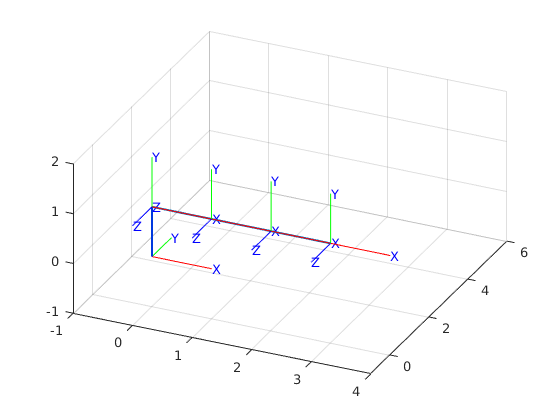

%Graficamos la trama absoluta o global 
trplot(H0,'rgb','axis', [-1 4 -1 6 -1 2])

%Realizamos una animación para la siguiente trama
%pause;

tranimate(H0, H1,'rgb','axis', [-1 4 -1 6 -1 2])
%Realizamos una animación para la siguiente trama
 %pause;
 tranimate(H1, H20,'rgb','axis', [-1 4 -1 6 -1 2])
% %Realizamos una animación para la siguiente trama
 %pause;
 tranimate(H20, H30,'rgb','axis', [-1 4 -1 6 -1 2])
 % %Realizamos una animación para la siguiente trama
 %pause;
 tranimate(H30, H40,'rgb','axis', [-1 4 -1 6 -1 2])

Para finalmente imprimir la matriz de transformacion homogenea global.

 disp(H40)

    1         0         0         3
    0         0        -1         0
    0         1         0         1
    0         0         0         1


Para los sistemas siguientes (2 y 3), se sigue el mismo procedimiento que el sistema 1, 

- Se   calculan las rotaciones y/0 trasformaciones que se necesarias para obtener las  matrices de transformacion homogeneas hasta llegar a la trama final.

- Se declaran las longitudes entre las tramas que estan en distintos puntos, buscando que el estas longitudes hagan que la simulacion sea lo mas parecida a al sistema.

- Se calculan las matrices de transformacion homogeneas con los resultados obtenido en el primer paso

- Se calcula la matriz de transformacion homogenea global

- Se configura el plano de simulacion y dibujan las lineas del sistema sobre las que se mueven las tramas.

- Se simulan cada una de las tramas

- Se imprime la matriz de tranformacion homogenea global

- Por ultimo se imprime la matriz de transformacion homogenea global

## Sistema 2 

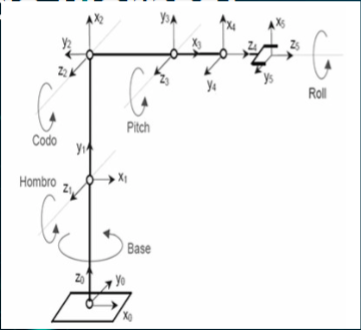

H1 = rotx(90) Tz(l1)

H2 = rotz(90) Ty(l2)

H3 = rotz(-90) Ty(-l3)

H4 = rotz(90)

H5 = rotx(90) Tx(l4)

H5 =  Tz(l5)

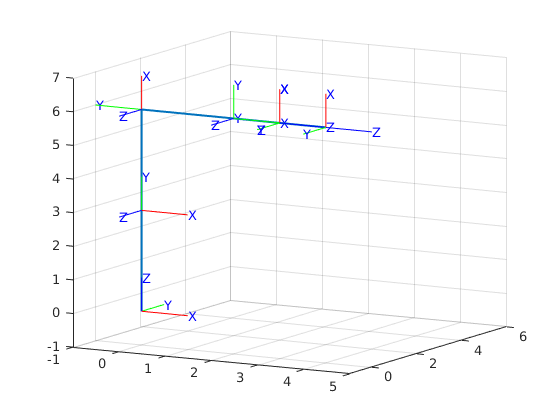

 %Limpieza de pantalla
clear all
close all
clc

%longitudes
l1 = 3;
l2 = 3;
l3 = 2; 
l4 = 1; 
l5 = 1; 


%Calculamos las matrices de transformación homogénea
H0=SE3;

H1=SE3(rotx(deg2rad(90)), [0 0 l1]);
H2=SE3(rotz(deg2rad(90)), [0 l2 0]);
H3=SE3(rotz(deg2rad(-90)),[0 -l3 0]);
H4=SE3(rotz(deg2rad(90)), [l4 0 0]);
H5=SE3(rotx(deg2rad(90)), [0 0 0]);
H6=SE3(rotz(0), [0 0 l5]);



H20= H1*H2;
H30= H20*H3; 
H40= H30*H4;
H50= H40*H5;
H60= H50*H6;%Matriz de transformación homogenea global de 3 a 0 

x=[0 0 4  ];
y=[0 0 0  ];
z=[0 6 6  ];

plot3(x, y, z,'LineWidth', 1.5); axis([-1 5 -1 6 -1 7]); grid on;
hold on;

%Graficamos la trama absoluta o global 
trplot(H0,'rgb','axis', [-1 5 -1 6 -1 7])

%Realizamos una animación para la siguiente trama
%pause;
view([29.70 11.40])

tranimate(H0, H1,'rgb','axis', [-1 5 -1 6 -1 7])
%Realizamos una animación para la siguiente trama
 %pause;
 tranimate(H1, H20,'rgb','axis', [-1 5 -1 6 -1 7])
% %Realizamos una animación para la siguiente trama
 %pause;
 tranimate(H20, H30,'rgb','axis', [-1 5 -1 6 -1 7])
 % %Realizamos una animación para la siguiente trama
 %pause;
 tranimate(H30, H40,'rgb','axis', [-1 5 -1 6 -1 7])
 % %Realizamos una animación para la siguiente trama
 %pause;
 tranimate(H40, H50,'rgb','axis', [-1 5 -1 6 -1 7])
 % %Realizamos una animación para la siguiente trama
 %pause;
 tranimate(H50, H60,'rgb','axis', [-1 5 -1 6 -1 7])



 disp(H60)

    0         0         1         4
    0        -1         0         0
    1         0         0         6
    0         0         0         1


## Sistema 3

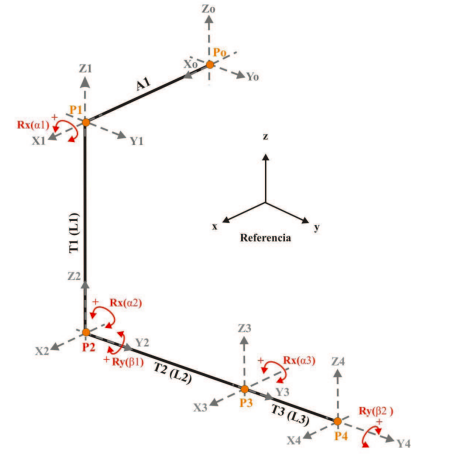

H1 = rotz(-90)

H2 =  Tx(l1)

H3 = Tz(-l2)

H4 = Ty(l3)

H5 = Ty(l4)

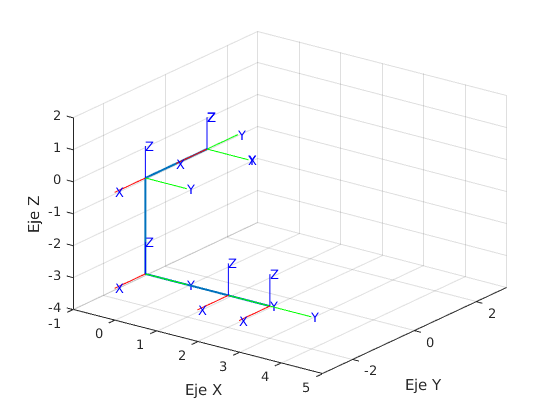

%Limpieza de pantalla
clear all
close all
clc

%longitudes
l1 = 2;
l2 = 3;
l3 = 2; 
l4 = 1;  


%Calculamos las matrices de transformación homogénea
H0=SE3;

H1=SE3(rotz(deg2rad(-90)), [0 0 0]);
H2=SE3(rotz(0), [l1 0 0]);
H3=SE3(rotz(0), [0 0 -l2]);
H4=SE3(rotz(0), [0 l3 0]);
H5=SE3(rotx(0), [0 l4 0]);

H20= H1*H2;
H30= H20*H3; 
H40= H30*H4;
H50= H40*H5; %Matriz de transformación homogenea global de 3 a 0 

x=[0  0  0  3];
y=[0 -2 -2 -2];
z=[0  0 -3 -3];

plot3(x, y, z,'LineWidth', 1.5); axis([-1 5 -3 3 -4 2]); grid on;
hold on;

% Establecer nombres de los ejes
xlabel('Eje X');
ylabel('Eje Y');
zlabel('Eje Z');

%Graficamos la trama absoluta o global 
trplot(H0,'rgb','axis', [-1 5 -3 3 -4 2])

%Realizamos una animación para la siguiente trama
%pause;

tranimate(H0, H1,'rgb','axis', [-1 5 -3 3 -4 2])
%Realizamos una animación para la siguiente trama
 %pause;
 tranimate(H1, H20,'rgb','axis', [-1 5 -3 3 -4 2])
% %Realizamos una animación para la siguiente trama
 %pause;
 tranimate(H20, H30,'rgb','axis', [-1 5 -3 3 -4 2])
 % %Realizamos una animación para la siguiente trama
 %pause;
 tranimate(H30, H40,'rgb','axis', [-1 5 -3 3 -4 2])
 % %Realizamos una animación para la siguiente trama
 %pause;
 tranimate(H40, H50,'rgb','axis', [-1 5 -3 3 -4 2])
 
view([36.60 29.40])

 disp(H50)

     0         1         0         3
    -1         0         0        -2
     0         0         1        -3
     0         0         0         1
